clear
addpath('..\..\utilities');
nodepos = load('input\input2\Np.mat').Np;
shearrates = load('input\input2\Shearrate.mat').SRnode;
shearrates(shearrates(:, :) == -1e+30) = 0;
temps = load('input\input2\Tnode.mat').Tnode;
fillstatus = load('input\input2\Fillstatus.mat').Fillstatus;
connectednodes = load('input\input2\connectedNodes.mat').connectedNodes;
connectedelements = load('input\input2\connectedElements.mat').connectedElements;
velx = load('input\input2\VelX.mat').VelX;
vely = load('input\input2\VelY.mat').VelY;
velz = load('input\input2\VelZ.mat').VelZ;

meshrefiner = meshRefiner;
easyvisualizer = easyVisualizer;
udmwriter = udmWriter;

elementnodeids = connectednodes + 1; % +1 so that indexing will work

[elementvellen, angle_deg] = meshrefiner.calcElementVelocities(elementnodeids, velx, vely, velz);

elementshearrates = meshrefiner.getElementValues(elementnodeids, shearrates);

% Mapping the coordinates of the centorids of the elements to the elements
elementcoordinates = easyvisualizer.getElementCoordinates(elementnodeids, nodepos);
elementnodesfilled = meshrefiner.getElementValues(elementnodeids, fillstatus);
% Calculating element fill status
elementfillstatus = meshrefiner.calcElementFillstatus(elementnodesfilled);

vellendiffs = meshrefiner.calcElementDiffs(elementvellen);
anglediffs = meshrefiner.calcElementDiffs(angle_deg);

% Akkor ez a rész már mehet egy az egyben a fejlesztés részbe, hogy miért
% ezek a paraaméterek adódtak ki faszán
[highvellendiffs, normalvellendiffs, highvellendiffsbytimestep] = meshrefiner.calcHighDiffElements(elementfillstatus, vellendiffs, 1.5, false);
[highanglediffs, normalanglediffs, highanglediffsbytimestep] = meshrefiner.calcHighDiffElements(elementfillstatus, anglediffs, 3, true);

highveldiffs = union(highvellendiffs(:, 1), highanglediffs(:, 1));
normalveldiffs = intersect(normalvellendiffs, normalanglediffs);

timestep = 16

timestep = 16

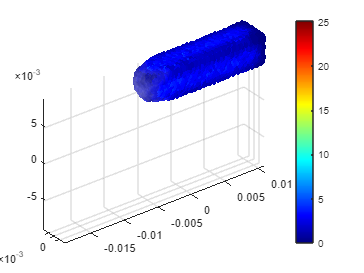

easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, vellendiffs, timestep, "no");

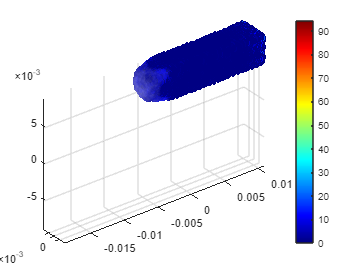

easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, anglediffs, timestep, "no");

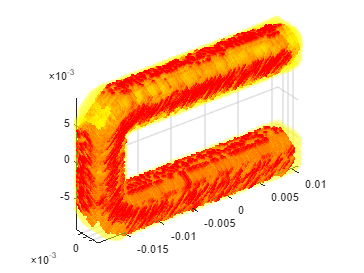

easyvisualizer.plotElementsToRefine(elementcoordinates, highvellendiffs, normalvellendiffs, 0)

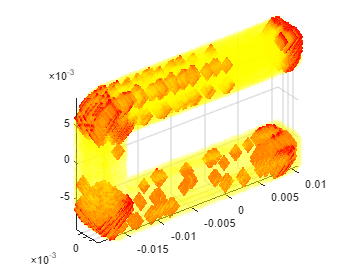

easyvisualizer.plotElementsToRefine(elementcoordinates, highanglediffs, normalanglediffs, 0)

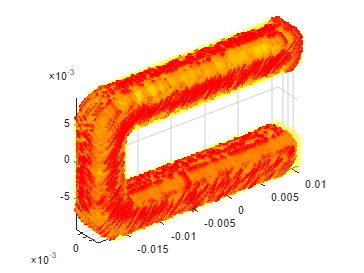

easyvisualizer.plotElementsToRefine(elementcoordinates, highveldiffs, normalveldiffs, 0)

tic
[newnodepos, newelementnodeids, affectedelements] = meshrefiner.createNewMeshMultiNode(nodepos, elementnodeids, highveldiffs);
toc

Elapsed time is 1235.032375 seconds.


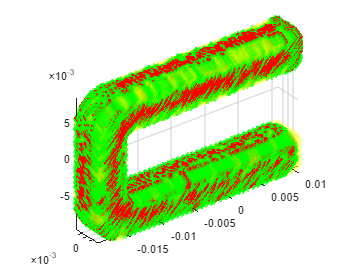

easyvisualizer.plotElementsToRefine(elementcoordinates, highveldiffs, normalveldiffs, affectedelements);

tic
udmwriter.createUDM(newnodepos, newelementnodeids, 'outputs/velocity_multinode.udm')
toc

Elapsed time is 87.016625 seconds.
